# **HW13**

## **Q1 [CORRECT]**

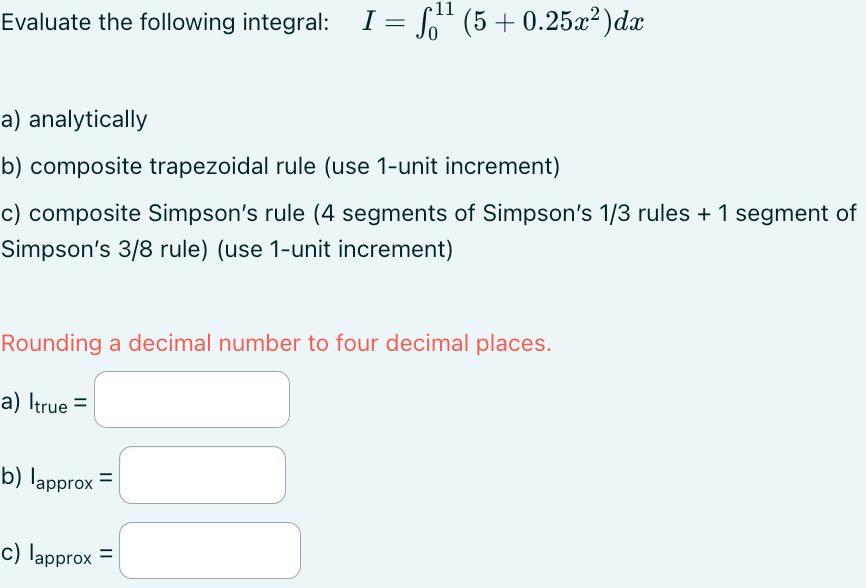 ***← Interesting (c)***

a = 0; b = 11;
x = 0:1:11;
f = @(x) 5 + 0.25.*x.^2;
Itrue = integral(f, a, b)
plot(x, f(x), '-')

Iapprox_trap = trap(f, a, b, (b - a))

% "1-unit increment" means h = 1
% "4 segments" means ns = 4

% Simpson's 1/3
%  ns #1      ns #2      ns #3      ns #4
%  0─1─2      2─3─4      4─5─6      6─7─8
% │──2h──│   │──2h──│   │──2h──│   │──2h──│
Isimpson13 = 0;
h1 = 1;
for i = [0 2 4 6] % the 4 left-ends are 0, 2, 4, 6 (+2h because it makes up 1 ns)
    x0 = a + i; % keep adding from the lower bound
    simpson13 = (h1/3) * ...
        ( f(x0) + ...
        (4*f(x0 + h1)) + ...
        (f(x0 + (2*h1))) );
    Isimpson13 = Isimpson13 + simpson13;
end

% Simpson's 3/8
%    ns #1
%  8─9─10─11
% │───3h────│
Isimpson38 = 0;
h2 = 1;
% no loop because there's 1 ns
x0 = 8;
simpson38 = ((3*h2)/8) * ...
    ( f(x0) + ...
    (3*f(x0 + h2)) + ...
    (3*f(x0 + (2*h2))) + ...
    (f(x0 + (3*h2))) );
Isimpson38 = Isimpson38 + simpson38;

Iapprox_simpsons = Isimpson13 + Isimpson38

% xs = linspace(0,11,400);  plot(xs,f(xs)), hold on
% for v=[0 2 4 6 8 11],  xline(v,'--'); end
% title({'Integration intervals', ...
%        'Simpson 1/3 on [0,8]  (four 2-unit panels)', ...
%        'Simpson 3/8 on [8,11] (one 3-unit panel)'})
% axis([0, 11.5, 5, 40])
% xlabel x, ylabel f(x), hold off

## Q2

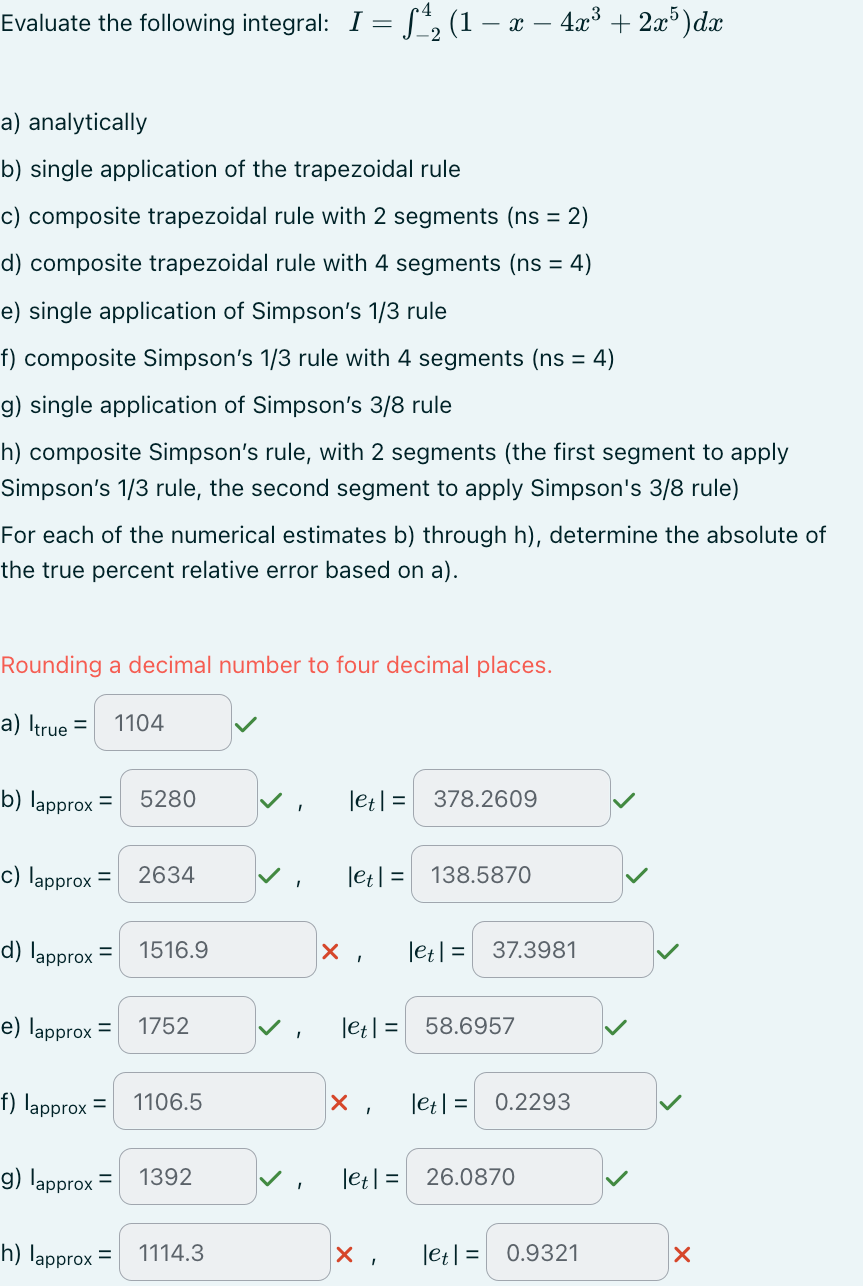

**Data**

format short
f = @(x) 1 - x - (4.*x.^3) + (2.*x.^5);
a = -2;
b = 4;
xx = a : 0.01 : b;
yy = f(xx);
plot(xx, yy, '-')

Itrue = integral(f, a, b)

**single application of the trapezoidal rule**


ns = 1
I_trap_ns1 = trap(f, a, b, ns)
abs_err_I_trap_ns1 = abs(((Itrue - I_trap_ns1) / Itrue) * 100)

**composite trapezoidal rule with 2 segments (ns = 2)**


ns = 2
I_trap_ns2 = trap(f, a, b, ns)
abs_err_I_trap_ns2 = abs(((Itrue - I_trap_ns2) / Itrue) * 100)

**composite trapezoidal rule with 4 segments (ns = 4)**


ns = 4
I_trap_ns4 = trap(f, a, b, ns)
abs_err_I_trap_ns4 = abs(((Itrue - I_trap_ns4) / Itrue) * 100)

**single application of Simpson’s 1/3 rule**


ns = 1
simpson13_ns1 = zeros(1, ns);
for i = 1:ns
    h = (b - a) / (2 * ns);
    left = (2*(i-1)*h) + a;
    simpson13_ns1 = (h/3) * ...
        ( f(left) + ...
        (4*f(left + h)) + ...
        f(left + (2*h)) );
end
I_simpson13_ns1 = sum(simpson13_ns1)
abs_err_I_simpson13_ns1 = abs(((Itrue - I_simpson13_ns1) / Itrue) * 100)

**composite Simpson’s 1/3 rule with 4 segments (ns = 4)**


ns = 4
I_simpson13_ns4 = 0;
for i = 1:ns
    h = (b - a) / (2 * ns);
    left = (2*(i-1)*h) + a;
    simpson13_ns4 = (h/3) * ...
        ( f(left) + ...
        (4*f(left + h)) + ...
        f(left + (2*h)) );
    I_simpson13_ns4 = I_simpson13_ns4 + simpson13_ns4;
end
I_simpson13_ns4
abs_err_I_simpson13_ns4 = abs(((Itrue - I_simpson13_ns4) / Itrue) * 100)

**single application of Simpson’s 3/8 rule**


ns = 1
I_simpson38_ns1 = 0;
for i = 1:ns
    h = (b - a) / (3 * ns);
    left = (3*(i-1)*h) + a;
    simpson38_ns1 = ((3*h)/8) * ...
        ( f(left) + ...
        (3*f(left + h)) + ...
        (3*f(left + (2*h))) + ...
        f(left + (3*h)) );
    I_simpson38_ns1 = I_simpson38_ns1 + simpson38_ns1;
end
I_simpson38_ns1
abs_err_I_simpson38_ns1 = abs(((Itrue - I_simpson38_ns1) / Itrue) * 100)

**composite Simpson’s rule, with 2 segments (the first segment to apply Simpson’s 1/3 rule, the second segment to apply Simpson's 3/8 rule)** ***[the step size is shared over the 2 segments]***



format default

% segment 1 (left-end)
a1 = -2; % a2 will be later determined when h is defined
% segment 2 (right-end)
b2 = 4; % b2 will be later determined when h is defined

% shared h
% (Simpson's 1/3 has 2 subsegments
%  Simpson's 3/8 has 3 subsegments
%  2 + 3 = 5 segments in total)
h = (b2 - a1) / 5;
a2 = 2*h % segment 1 (right-end)
b1 = 2*h % segment 2 (left-end)

simpson13 = (h/3) * ...
    ( f(a1) + ...
    (4*f(a1 + h)) + ...
    f(a1 + (2*h)) );

simpson38 = ((3*h)/8) * ...
    ( f(a2) + ...
    (3*f(a2 + h)) + ...
    (3*f(a2 + (2*h))) + ...
    f(a2 + (3*h)) );

combined = round(simpson13 + simpson38, 4)
abs_err_combined = round(abs(((Itrue - combined) / Itrue) * 100), 4)

## Q3 [CORRECT]

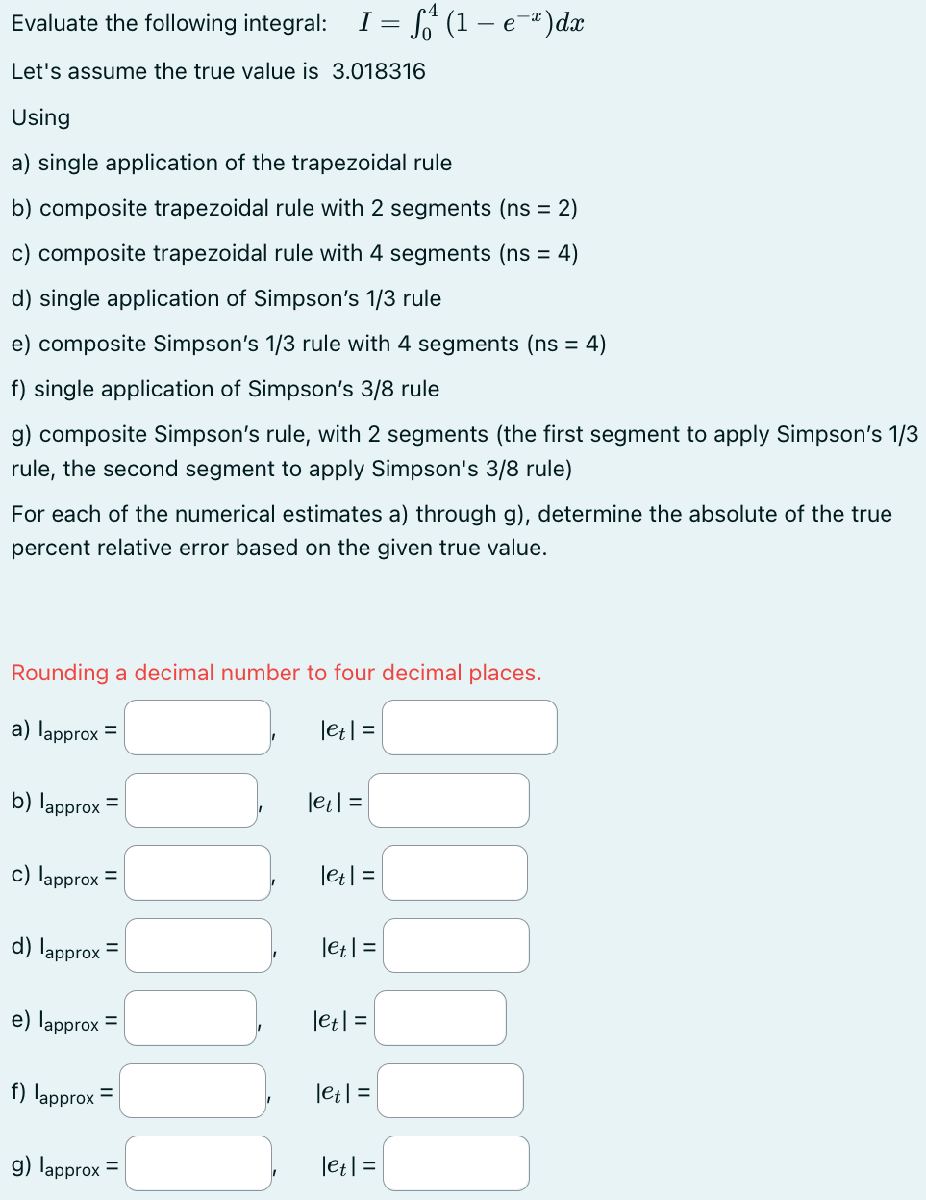

**Data**

f = @(x) 1 - exp(-x);
xx = 0 : 0.01 : 4;
yy = f(xx);
Itrue = 3.018316;
a = 0;
b = 4;
plot(xx, yy, '-')

**a) single application of the trapezoidal rule**


ns = 1
I_trap_ns1 = trap(f, a, b, ns)
abs_err_I_trap_ns1 = abs(((Itrue - I_trap_ns1) / Itrue) * 100)

**b) composite trapezoidal rule with 2 segments (ns = 2)**


ns = 2
I_trap_ns2 = trap(f, a, b, ns)
abs_err_I_trap_ns2 = abs(((Itrue - I_trap_ns2) / Itrue) * 100)

**c) composite trapezoidal rule with 4 segments (ns = 4)**


ns = 4
I_trap_ns4 = trap(f, a, b, ns)
abs_err_I_trap_ns4 = abs(((Itrue - I_trap_ns4) / Itrue) * 100)

**d) single application of Simpson’s 1/3 rule**


ns = 1
simpson13_ns1 = zeros(1, ns);
for i = 1:ns
    h = (b - a) / (2 * ns);
    left = (2*(i-1)*h) + a;
    simpson13_ns1 = (h/3) * ...
        ( f(left) + ...
        (4*f(left + h)) + ...
        f(left + (2*h)) );
end
I_simpson13_ns1 = sum(simpson13_ns1)
abs_err_I_simpson13_ns1 = abs(((Itrue - I_simpson13_ns1) / Itrue) * 100)

**e) composite Simpson’s 1/3 rule with 4 segments (ns = 4)**


ns = 4
I_simpson13_ns4 = 0;
for i = 1:ns
    h = (b - a) / (2 * ns);
    left = (2*(i-1)*h) + a;
    simpson13_ns4 = (h/3) * ...
        ( f(left) + ...
        (4*f(left + h)) + ...
        f(left + (2*h)) );
    I_simpson13_ns4 = I_simpson13_ns4 + simpson13_ns4;
end
I_simpson13_ns4
abs_err_I_simpson13_ns4 = abs(((Itrue - I_simpson13_ns4) / Itrue) * 100)

**f) single application of Simpson’s 3/8 rule**


ns = 1
I_simpson38_ns1 = 0;
for i = 1:ns
    h = (b - a) / (3 * ns);
    left = (3*(i-1)*h) + a;
    simpson38_ns1 = ((3*h)/8) * ...
        ( f(left) + ...
        (3*f(left + h)) + ...
        (3*f(left + (2*h))) + ...
        f(left + (3*h)) );
    I_simpson38_ns1 = I_simpson38_ns1 + simpson38_ns1;
end
I_simpson38_ns1
abs_err_I_simpson38_ns1 = abs(((Itrue - I_simpson38_ns1) / Itrue) * 100)

**g) composite Simpson’s rule, with 2 segments (the first segment to apply Simpson’s 1/3 rule, the second segment to apply Simpson's 3/8 rule)** ***[the step size is shared over the 2 segments]***



format short

% segment 1 (left-end)
a1 = 0; % a2 will be later determined when h is defined
% segment 2 (right-end)
b2 = 4; % b2 will be later determined when h is defined

% shared h
% (Simpson's 1/3 has 2 subsegments
%  Simpson's 3/8 has 3 subsegments
%  2 + 3 = 5 segments in total)
h = (b2 - a1) / 5;
a2 = 2*h % segment 1 (right-end)
b1 = 2*h % segment 2 (left-end)

simpson13 = (h/3) * ...
    ( f(a1) + ...
    (4*f(a1 + h)) + ...
    f(a1 + (2*h)) );

simpson38 = ((3*h)/8) * ...
    ( f(a2) + ...
    (3*f(a2 + h)) + ...
    (3*f(a2 + (2*h))) + ...
    f(a2 + (3*h)) );

combined = simpson13 + simpson38
abs_err_combined = abs(((Itrue - combined) / Itrue) * 100)

## Q4

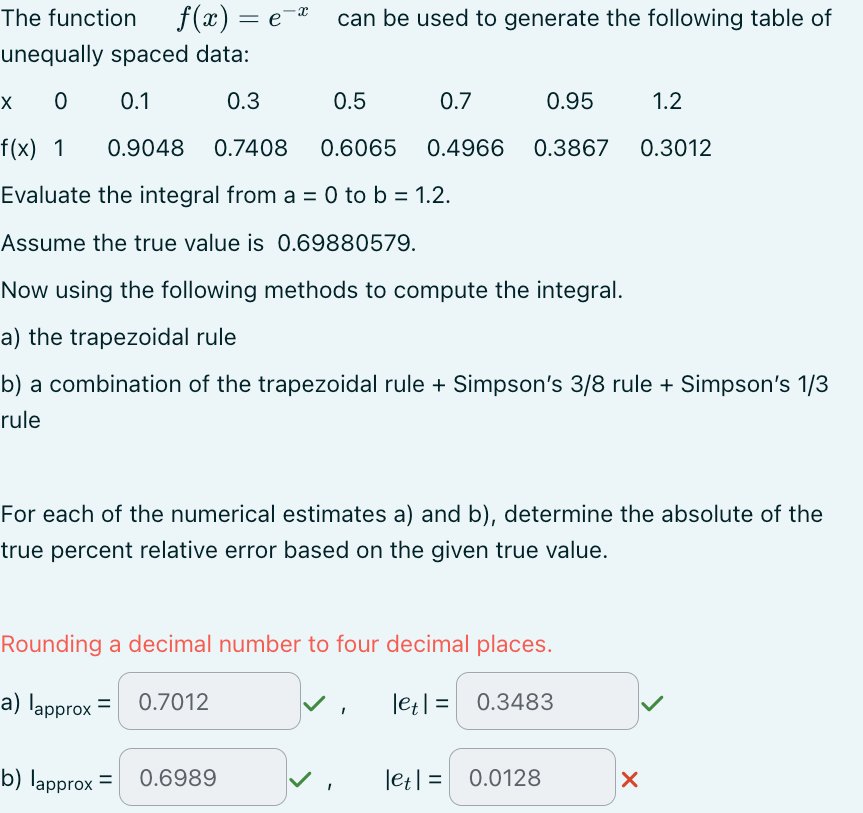

### a

x = [0 	  0.1 	  0.3 	  0.5 	  0.7 	  0.95 	  1.2];
y = [1 	0.9048 	0.7408 	0.6065 	0.4966 	0.3867 	0.3012];
a = 0; b = 1.2; Itrue = 0.69880579;

f = @(x) exp(-x)

f = 値をもつ function_handle :
    @(x)exp(-x)


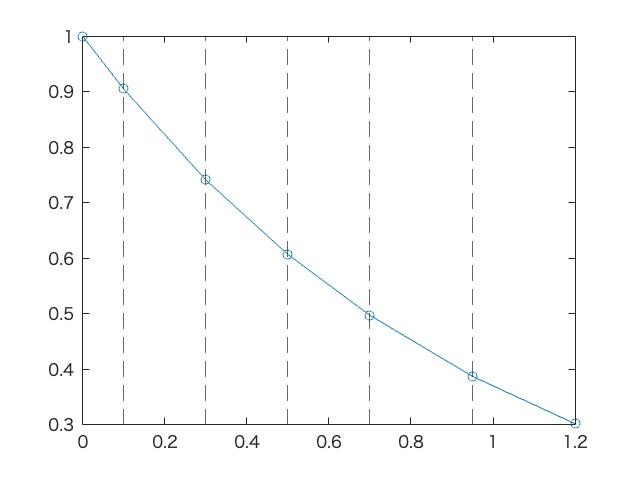


figure
plot(x, y, 'o-')
hold on
for i=x
    xline(i,'--')
end
hold off


Itrap = trapuneq(x, y)

Itrap = 0.7012

errtrap = round(abs((Itrue - Itrap) / Itrue) * 100, 4)

errtrap = 0.3483

### b

x2 = [0 0.1];
y2 = [1 0.9048];
Itrap2 = trapuneq(x2, y2)

Itrap2 = 0.0952

errtrap2 = round(abs((Itrue - Itrap2) / Itrue) * 100, 4)

errtrap2 = 86.3710


% [0.1 0.3 0.5 0.7] (no loop; already covered whole)
h38 = 0.2;
left = 0.1;
simpson38 = ((3*h38)/8) * ...
    ( f(left) + ...
    (3*f(left + h38)) + ...
    (3*f(left + (2*h38))) + ...
    f(left + (3*h38)) );

% [0.7 0.95 1.2] (no loop; already covered whole)
h13 = 0.25;
left = 0.7;
simpson13 = (h13/3) * ...
    ( f(left) + ...
    (4*f(left + h13)) + ...
    f(left + (2*h13)) );

Icombined = Itrap2 + simpson38 + simpson13

Icombined = 0.6989

errcombined = round(abs((Itrue - Icombined) / Itrue) * 100, 4)

errcombined = 0.0128

## Q5

**Data**

format short

f = @(x) 8 + (4*cos(x));
xx = 0 : 0.01 : 4;
yy = f(xx);
Itrue = 16.56637;
a = 0;
b = 3.141592653589793/2;
plot(xx, yy, '-')

**a) single application of the trapezoidal rule**


ns = 1
I_trap_ns1 = trap(f, a, b, ns)
abs_err_I_trap_ns1 = abs(((Itrue - I_trap_ns1) / Itrue) * 100)

**b) composite trapezoidal rule with 2 segments (ns = 2)**


ns = 2
I_trap_ns2 = trap(f, a, b, ns)
abs_err_I_trap_ns2 = abs(((Itrue - I_trap_ns2) / Itrue) * 100)

**c) composite trapezoidal rule with 4 segments (ns = 4)**


ns = 4
I_trap_ns4 = trap(f, a, b, ns)
abs_err_I_trap_ns4 = abs(((Itrue - I_trap_ns4) / Itrue) * 100)

**d) single application of Simpson’s 1/3 rule**


ns = 1
simpson13_ns1 = zeros(1, ns);
for i = 1:ns
    h = (b - a) / (2 * ns);
    left = (2*(i-1)*h) + a;
    simpson13_ns1 = (h/3) * ...
        ( f(left) + ...
        (4*f(left + h)) + ...
        f(left + (2*h)) );
end
I_simpson13_ns1 = sum(simpson13_ns1)
abs_err_I_simpson13_ns1 = abs(((Itrue - I_simpson13_ns1) / Itrue) * 100)

**e) composite Simpson’s 1/3 rule with 4 segments (ns = 4)**

format default
ns = 4
I_simpson13_ns4 = 0;
for i = 1:ns
    h = (b - a) / (2 * ns);
    left = (2*(i-1)*h) + a;
    simpson13_ns4 = (h/3) * ...
        ( f(left) + ...
        (4*f(left + h)) + ...
        f(left + (2*h)) );
    I_simpson13_ns4 = I_simpson13_ns4 + simpson13_ns4;
end
I_simpson13_ns4
abs_err_I_simpson13_ns4 = round(abs(((Itrue - I_simpson13_ns4) / Itrue) * 100), 4)

**f) single application of Simpson’s 3/8 rule**


ns = 1
I_simpson38_ns1 = 0;
for i = 1:ns
    h = (b - a) / (3 * ns);
    left = (3*(i-1)*h) + a;
    simpson38_ns1 = ((3*h)/8) * ...
        ( f(left) + ...
        (3*f(left + h)) + ...
        (3*f(left + (2*h))) + ...
        f(left + (3*h)) );
    I_simpson38_ns1 = I_simpson38_ns1 + simpson38_ns1;
end
I_simpson38_ns1
abs_err_I_simpson38_ns1 = abs(((Itrue - I_simpson38_ns1) / Itrue) * 100)

**g) composite Simpson’s rule, with 2 segments (the first segment to apply Simpson’s 1/3 rule, the second segment to apply Simpson's 3/8 rule)** ***[the step size is shared over the 2 segments]***



format short

% segment 1 (left-end)
a1 = 0; % a2 will be later determined when h is defined
% segment 2 (right-end)
b2 = 3.141592653589793/2; % b2 will be later determined when h is defined

% shared h
% (Simpson's 1/3 has 2 subsegments
%  Simpson's 3/8 has 3 subsegments
%  2 + 3 = 5 segments in total)
h = (b2 - a1) / 5;
a2 = 2*h % segment 1 (right-end)
b1 = 2*h % segment 2 (left-end)

simpson13 = (h/3) * ...
    ( f(a1) + ...
    (4*f(a1 + h)) + ...
    f(a1 + (2*h)) );

simpson38 = ((3*h)/8) * ...
    ( f(a2) + ...
    (3*f(a2 + h)) + ...
    (3*f(a2 + (2*h))) + ...
    f(a2 + (3*h)) );

combined = simpson13 + simpson38
abs_err_combined = abs(((Itrue - combined) / Itrue) * 100)